clear all


syms x r_x K_x alpha_xy delta_x y r_y K_y alpha_yx delta_y m a q delta_m d_m f
eqns2spp = [r_x*((K_x-x-alpha_xy*y)/K_x) - delta_x == 0, r_y*((K_y-y-alpha_yx*x)/K_y) - delta_y == 0];
solution2spp = solve(eqns2spp,[x, y])

solution2spp = struct with fields:
    x: -(K_x*delta_x*r_y - K_x*r_x*r_y - K_y*alpha_xy*delta_y*r_x + K_y*alpha_xy*r_x*r_y)/(r_x*(r_y - alpha_xy*alpha_yx*r_y))
    y: -(K_y*delta_y*r_x - K_y*r_x*r_y - K_x*alpha_yx*delta_x*r_y + K_x*alpha_yx*r_x*r_y)/(r_x*(r_y - alpha_xy*alpha_yx*r_y))


displaySymSolution(solution2spp)

solution2spp = struct with fields:
    x: -(K_x*delta_x*r_y - K_x*r_x*r_y - K_y*alpha_xy*delta_y*r_x + K_y*alpha_xy*r_x*r_y)/(r_x*(r_y - alpha_xy*alpha_yx*r_y))
    y: -(K_y*delta_y*r_x - K_y*r_x*r_y - K_x*alpha_yx*delta_x*r_y + K_x*alpha_yx*r_x*r_y)/(r_x*(r_y - alpha_xy*alpha_yx*r_y))


where


$$\left(\begin{array}{cc} x & y \end{array}\right)=\left(\begin{array}{cc} -\frac{K_{x}\,\delta_{x}\,r_{y}-K_{x}\,r_{x}\,r_{y}-K_{y}\,\alpha_{\mathrm{xy}}\,\delta_{y}\,r_{x}+K_{y}\,\alpha_{\mathrm{xy}}\,r_{x}\,r_{y}}{r_{x}\,\left(r_{y}-\alpha_{\mathrm{xy}}\,\alpha_{\mathrm{yx}}\,r_{y}\right)} & -\frac{K_{y}\,\delta_{y}\,r_{x}-K_{y}\,r_{x}\,r_{y}-K_{x}\,\alpha_{\mathrm{yx}}\,\delta_{x}\,r_{y}+K_{x}\,\alpha_{\mathrm{yx}}\,r_{x}\,r_{y}}{r_{x}\,\left(r_{y}-\alpha_{\mathrm{xy}}\,\alpha_{\mathrm{yx}}\,r_{y}\right)} \end{array}\right)$$

%%
syms x r_x K_x alpha_xy delta_x y r_y K_y alpha_yx delta_y m a q delta_m d_m f
eqns = [r_x*((K_x-x-alpha_xy*y)/K_x) - a*m - delta_x == 0, r_y*((K_y-y-alpha_yx*x)/K_y) - delta_y == 0, a*q*x - delta_m - d_m*m == 0];
eqns2spp_xm = [r_x*((K_x-x-alpha_xy*y)/K_x) - a*m - delta_x == 0, a*q*x - delta_m - d_m*m == 0];
soln2spp_xm = solve(eqns2spp_xm,[x,m])

soln2spp_xm = struct with fields:
    x: (K_x*a*delta_m - K_x*d_m*delta_x + K_x*d_m*r_x - alpha_xy*d_m*r_x*y)/(K_x*q*a^2 + d_m*r_x)
    m: -(delta_m*r_x + K_x*a*delta_x*q - K_x*a*q*r_x + a*alpha_xy*q*r_x*y)/(K_x*q*a^2 + d_m*r_x)


displaySymSolution(soln2spp_xm)

soln2spp_xm = struct with fields:
    x: (K_x*a*delta_m - K_x*d_m*delta_x + K_x*d_m*r_x - alpha_xy*d_m*r_x*y)/(K_x*q*a^2 + d_m*r_x)
    m: -(delta_m*r_x + K_x*a*delta_x*q - K_x*a*q*r_x + a*alpha_xy*q*r_x*y)/(K_x*q*a^2 + d_m*r_x)


where


$$\left(\begin{array}{cc} x & m \end{array}\right)=\left(\begin{array}{cc} \frac{K_{x}\,a\,\delta_{m}-K_{x}\,d_{m}\,\delta_{x}+K_{x}\,d_{m}\,r_{x}-\alpha_{\mathrm{xy}}\,d_{m}\,r_{x}\,y}{K_{x}\,q\,a^{2}+d_{m}\,r_{x}} & -\frac{\delta_{m}\,r_{x}+K_{x}\,a\,\delta_{x}\,q-K_{x}\,a\,q\,r_{x}+a\,\alpha_{\mathrm{xy}}\,q\,r_{x}\,y}{K_{x}\,q\,a^{2}+d_{m}\,r_{x}} \end{array}\right)$$

%%


% Compute simplified symbolic expression
eqns

$$eqns = \left(\begin{array}{ccc} -\delta_{x}-a\,m-\frac{r_{x}\,\left(x-K_{x}+\alpha_{\mathrm{xy}}\,y\right)}{K_{x}}=0 & -\delta_{y}-\frac{r_{y}\,\left(y-K_{y}+\alpha_{\mathrm{yx}}\,x\right)}{K_{y}}=0 & a\,q\,x-d_{m}\,m-\delta_{m}=0 \end{array}\right)$$

simplifiedExpr = combine(eqns);

% Compute analytic solution of a symbolic equation
solution = solve(eqns,[x,y,m]);
% Display symbolic solution returned by solve
displaySymSolution(solution);

solution = struct with fields:
    x: (K_x*a*delta_m*r_y - K_x*d_m*delta_x*r_y + K_x*d_m*r_x*r_y + K_y*alpha_xy*d_m*delta_y*r_x - K_y*alpha_xy*d_m*r_x*r_y)/(r_y*(K_x*q*a^2 + d_m*r_x - alpha_xy*alpha_yx*d_m*r_x))
    y: -(K_y*d_m*delta_y*r_x - K_y*d_m*r_x*r_y + K_x*a*alpha_yx*delta_m*r_y - K_x*alpha_yx*d_m*delta_x*r_y + K_x*alpha_yx*d_m*r_x*r_y + K_x*K_y*a^2*delta_y*q - K_x*K_y*a^2*q*r_y)/(r_y*(K_x*q*a^2 + d_m*r_x - alpha_xy*alpha_yx*d_m*r_x))
    m: -(delta_m*r_x*r_y + K_x*a*delta_x*q*r_y - K_x*a*q*r_x*r_y - alpha_xy*alpha_yx*delta_m*r_x*r_y - K_y*a*alpha_xy*delta_y*q*r_x + K_y*a*alpha_xy*q*r_x*r_y)/(r_y*(K_x*q*a^2 + d_m*r_x - alpha_xy*alpha_yx*d_m*r_x))


where


$$\begin{array}{l} \left(\begin{array}{ccc} x & y & m \end{array}\right)=\left(\begin{array}{ccc} \frac{K_{x}\,a\,\delta_{m}\,r_{y}-K_{x}\,d_{m}\,\delta_{x}\,r_{y}+K_{x}\,d_{m}\,r_{x}\,r_{y}+K_{y}\,\alpha_{\mathrm{xy}}\,d_{m}\,\delta_{y}\,r_{x}-K_{y}\,\alpha_{\mathrm{xy}}\,d_{m}\,r_{x}\,r_{y}}{\sigma_{1}} & -\frac{K_{y}\,d_{m}\,\delta_{y}\,r_{x}-K_{y}\,d_{m}\,r_{x}\,r_{y}+K_{x}\,a\,\alpha_{\mathrm{yx}}\,\delta_{m}\,r_{y}-K_{x}\,\alpha_{\mathrm{yx}}\,d_{m}\,\delta_{x}\,r_{y}+K_{x}\,\alpha_{\mathrm{yx}}\,d_{m}\,r_{x}\,r_{y}+K_{x}\,K_{y}\,a^{2}\,\delta_{y}\,q-K_{x}\,K_{y}\,a^{2}\,q\,r_{y}}{\sigma_{1}} & -\frac{\delta_{m}\,r_{x}\,r_{y}+K_{x}\,a\,\delta_{x}\,q\,r_{y}-K_{x}\,a\,q\,r_{x}\,r_{y}-\alpha_{\mathrm{xy}}\,\alpha_{\mathrm{yx}}\,\delta_{m}\,r_{x}\,r_{y}-K_{y}\,a\,\alpha_{\mathrm{xy}}\,\delta_{y}\,q\,r_{x}+K_{y}\,a\,\alpha_{\mathrm{xy}}\,q\,r_{x}\,r_{y}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{y}\,\left(K_{x}\,q\,a^{2}+d_{m}\,r_{x}-\alpha_{\mathrm{xy}}\,\alpha_{\mathrm{yx}}\,d_{m}\,r_{x}\right) \end{array}$$

% Compute analytic solution of a symbolic equation
solution = solve(eqns,[x,y,m]);
% Display symbolic solution returned by solve
displaySymSolution(solution);

solution = struct with fields:
    x: (K_x*a*delta_m*r_y - K_x*d_m*delta_x*r_y + K_x*d_m*r_x*r_y + K_y*alpha_xy*d_m*delta_y*r_x - K_y*alpha_xy*d_m*r_x*r_y)/(r_y*(K_x*q*a^2 + d_m*r_x - alpha_xy*alpha_yx*d_m*r_x))
    y: -(K_y*d_m*delta_y*r_x - K_y*d_m*r_x*r_y + K_x*a*alpha_yx*delta_m*r_y - K_x*alpha_yx*d_m*delta_x*r_y + K_x*alpha_yx*d_m*r_x*r_y + K_x*K_y*a^2*delta_y*q - K_x*K_y*a^2*q*r_y)/(r_y*(K_x*q*a^2 + d_m*r_x - alpha_xy*alpha_yx*d_m*r_x))
    m: -(delta_m*r_x*r_y + K_x*a*delta_x*q*r_y - K_x*a*q*r_x*r_y - alpha_xy*alpha_yx*delta_m*r_x*r_y - K_y*a*alpha_xy*delta_y*q*r_x + K_y*a*alpha_xy*q*r_x*r_y)/(r_y*(K_x*q*a^2 + d_m*r_x - alpha_xy*alpha_yx*d_m*r_x))


where


$$\begin{array}{l} \left(\begin{array}{ccc} x & y & m \end{array}\right)=\left(\begin{array}{ccc} \frac{K_{x}\,a\,\delta_{m}\,r_{y}-K_{x}\,d_{m}\,\delta_{x}\,r_{y}+K_{x}\,d_{m}\,r_{x}\,r_{y}+K_{y}\,\alpha_{\mathrm{xy}}\,d_{m}\,\delta_{y}\,r_{x}-K_{y}\,\alpha_{\mathrm{xy}}\,d_{m}\,r_{x}\,r_{y}}{\sigma_{1}} & -\frac{K_{y}\,d_{m}\,\delta_{y}\,r_{x}-K_{y}\,d_{m}\,r_{x}\,r_{y}+K_{x}\,a\,\alpha_{\mathrm{yx}}\,\delta_{m}\,r_{y}-K_{x}\,\alpha_{\mathrm{yx}}\,d_{m}\,\delta_{x}\,r_{y}+K_{x}\,\alpha_{\mathrm{yx}}\,d_{m}\,r_{x}\,r_{y}+K_{x}\,K_{y}\,a^{2}\,\delta_{y}\,q-K_{x}\,K_{y}\,a^{2}\,q\,r_{y}}{\sigma_{1}} & -\frac{\delta_{m}\,r_{x}\,r_{y}+K_{x}\,a\,\delta_{x}\,q\,r_{y}-K_{x}\,a\,q\,r_{x}\,r_{y}-\alpha_{\mathrm{xy}}\,\alpha_{\mathrm{yx}}\,\delta_{m}\,r_{x}\,r_{y}-K_{y}\,a\,\alpha_{\mathrm{xy}}\,\delta_{y}\,q\,r_{x}+K_{y}\,a\,\alpha_{\mathrm{xy}}\,q\,r_{x}\,r_{y}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{y}\,\left(K_{x}\,q\,a^{2}+d_{m}\,r_{x}-\alpha_{\mathrm{xy}}\,\alpha_{\mathrm{yx}}\,d_{m}\,r_{x}\right) \end{array}$$


num_sol = solve(subs(eqns,[r_x K_x alpha_xy delta_x r_y K_y alpha_yx delta_y a d_m], [5,200,0.73,0.01,5,200,0.60,0.03,1,1]),[x,y,m])

num_sol = struct with fields:
    x: (2*(10000*delta_m + 13619))/(20000*q + 281)
    y: (160*(24850*q - 75*delta_m + 247))/(20000*q + 281)
    m: -(281*delta_m - 27238*q)/(20000*q + 281)


displaySymSolution(num_sol);

num_sol = struct with fields:
    x: (2*(10000*delta_m + 13619))/(20000*q + 281)
    y: (160*(24850*q - 75*delta_m + 247))/(20000*q + 281)
    m: -(281*delta_m - 27238*q)/(20000*q + 281)


where


$$\left(\begin{array}{ccc} x & y & m \end{array}\right)=\left(\begin{array}{ccc} \frac{2\,\left(10000\,\delta_{m}+13619\right)}{20000\,q+281} & \frac{160\,\left(24850\,q-75\,\delta_{m}+247\right)}{20000\,q+281} & -\frac{281\,\delta_{m}-27238\,q}{20000\,q+281} \end{array}\right)$$

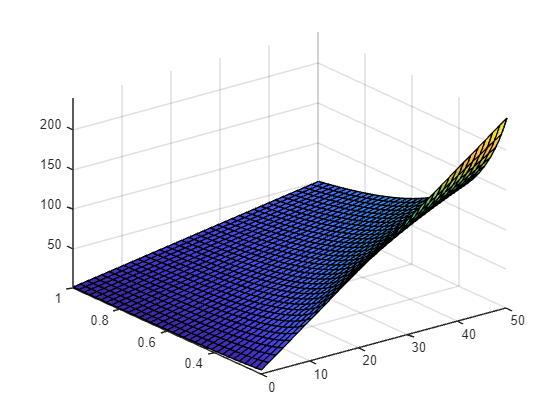


%
fsurf(delta_m,q,num_sol.x,[0 50 0.2 1])
% fsurf(delta_m,q,num_sol.y,[0 50 0.2 1])
% fsurf(delta_m,q,num_sol.m,[0 50 0.2 1])
hold off

syms p_x p_y p_m c_x0 c_xm c_xym c_xy c_y0 c_ym c_yxm c_yx c_mx c_mxy c_my e_x0 e_xy e_xm e_xym e_y0 e_yx e_ym e_yxm ...
    e_mx e_mxy e_my 

eqns2 = [(c_x0*(1-p_x)-e_x0)*(1-(p_m+p_y)+p_y*p_m) + (c_xm*(1-p_x)-e_xm)*p_m*(1-p_y) + (c_xy*(1-p_x)-e_xy)*p_y*(1-p_m) + (c_xym*(1-p_x)-e_xym)*p_y*p_m == 0;...
    (c_y0*(1-p_y)-e_y0)*(1-(p_m+p_x)+p_x*p_m) + (c_ym*(1-p_y)-e_ym)*p_m*(1-p_x) + (c_yx*(1-p_y)-e_yx)*p_x*(1-p_m) + (c_yxm*(1-p_y)-e_yxm)*p_x*p_m == 0;...
    (c_mx*(1-p_m)-e_mx)*(1-p_y)*p_x+ (c_my*(1-p_m)-e_my)*(1-p_x)*p_y+ (c_mxy*(1-p_m)-e_mxy)*p_y*p_x == 0];

simplifiedExpr2 = combine(eqns2);
%solution2 = simplify(solve(eqns2,p_m));
% Display symbolic solution returned by solve
%displaySymSolution(solution2);

% num_sol = solve(subs(eqns,[r_x K_x alpha_xy delta_x r_y K_y alpha_yx delta_y a d_m], [5,200,0.73,0.01,5,200,0.60,0.03,1,1]),[x,y,m])
% displaySymSolution(num_sol);

clear all
syms x r_x K_x alpha_xy delta_x y r_y K_y alpha_yx delta_y m a q delta_m d_m f
eqns3 = [r_x*((K_x-x-alpha_xy*y)/K_x) - a*f*m - delta_x == 0, r_y*((K_y-y-alpha_yx*x)/K_y) - a*(1-f)*m - delta_y == 0, a*q*(f*x+(1-f)*y) - delta_m - d_m*m == 0];
eqns3_og = [r_x*x*((K_x-x-alpha_xy*y)/K_x) - a*f*m*x - delta_x*x == 0, r_y*y*((K_y-y-alpha_yx*x)/K_y) - a*(1-f)*m*y - delta_y*y == 0, a*q*m*(f*x+(1-f)*y) - delta_m*m - d_m*m*m == 0]

$$eqns3\_og = \left(\begin{array}{ccc} -\delta_{x}\,x-a\,f\,m\,x-\frac{r_{x}\,x\,\left(x-K_{x}+\alpha_{\mathrm{xy}}\,y\right)}{K_{x}}=0 & a\,m\,y\,\left(f-1\right)-\delta_{y}\,y-\frac{r_{y}\,y\,\left(y-K_{y}+\alpha_{\mathrm{yx}}\,x\right)}{K_{y}}=0 & a\,m\,q\,\left(f\,x-y\,\left(f-1\right)\right)-d_{m}\,m^{2}-\delta_{m}\,m=0 \end{array}\right)$$


simplifiedExpr = combine(eqns3);
solution3 = solve(eqns3,[x,y,m]);
% Display symbolic solution returned by solve
displaySymSolution(solution3);

solution3 = struct with fields:
    x: (K_x*d_m*r_x*r_y - K_x*d_m*delta_x*r_y - K_y*a*alpha_xy*delta_m*r_x + K_y*alpha_xy*d_m*delta_y*r_x + K_x*a*delta_m*f*r_y - K_y*alpha_xy*d_m*r_x*r_y - K_x*K_y*a^2*delta_x*q + K_x*K_y*a^2*q*r_x - K_x*K_y*a^2*delta_x*f^2*q - K_x*K_y*a^2*delta_y*f^…
    y: -(K_y*d_m*delta_y*r_x - K_y*a*delta_m*r_x - K_y*d_m*r_x*r_y - K_x*alpha_yx*d_m*delta_x*r_y + K_y*a*delta_m*f*r_x + K_x*alpha_yx*d_m*r_x*r_y + K_x*K_y*a^2*delta_x*f^2*q + K_x*K_y*a^2*delta_y*f^2*q - K_x*K_y*a^2*f^2*q*r_x - K_x*K_y*a^2*f^2*q*r_y …
    m: -(delta_m*r_x*r_y + K_y*a*delta_y*q*r_x - K_y*a*q*r_x*r_y - alpha_xy*alpha_yx*delta_m*r_x*r_y - K_x*a*alpha_yx*delta_x*q*r_y + K_x*a*delta_x*f*q*r_y - K_y*a*delta_y*f*q*r_x + K_x*a*alpha_yx*q*r_x*r_y - K_x*a*f*q*r_x*r_y + K_y*a*f*q*r_x*r_y + K_…


where



num_sol = solve(subs(eqns3,[r_x K_x alpha_xy delta_x r_y K_y alpha_yx delta_y a d_m f], [5,200,0.73,0.01,5,200,0.60,0.03,1,1, 0.7]),[x,y,m]);
displaySymSolution(num_sol);

num_sol = struct with fields:
    x: (2*(4810*delta_m - 237840*q + 13619))/(6014*q + 281)
    y: (160*(6937*q - 15*delta_m + 247))/(6014*q + 281)
    m: -(1405*delta_m - 154613*q)/(5*(6014*q + 281))


where


$$\left(\begin{array}{ccc} x & y & m \end{array}\right)=\left(\begin{array}{ccc} \frac{2\,\left(4810\,\delta_{m}-237840\,q+13619\right)}{6014\,q+281} & \frac{160\,\left(6937\,q-15\,\delta_{m}+247\right)}{6014\,q+281} & -\frac{1405\,\delta_{m}-154613\,q}{5\,\left(6014\,q+281\right)} \end{array}\right)$$


%fsurf(delta_m,q,num_sol.x,[0 40 0.2 1])
%fsurf(delta_m,q,num_sol.y,[0 40 0.2 1])
%fsurf(delta_m,q,num_sol.m,[0 40 0.2 1])